# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0737   -0.0137   -0.0549   -0.0778   -0.0735   -0.0771   -0.0750   -0.0737   -0.0737   -0.0735   -0.0738   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737   -0.0737
   -0.0403   -0.0405   -0.0157   -0.0249   -0.0475   -0.0429   -0.0404   -0.0403   -0.0403   -0.0402   -0.0404   -0.0404   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0.0403   -0

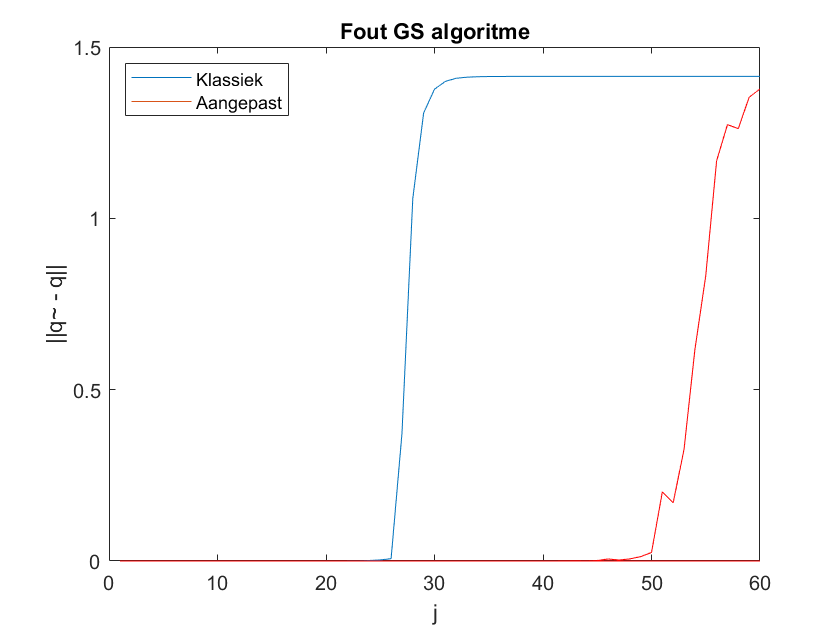


% Oefening 4
e1 = zeros(n);
e2 = zeros(n);

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest') % fout is exponentieel ma geen idee waarom

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0485   -0.0568   -0.0815
    0.0638    0.0002    0.0529
    0.0101   -0.0002   -0.0141
   -0.0170   -0.0108   -0.0211
   -0.0469   -0.0397   -0.0515
   -0.0317   -0.0427   -0.0284
    0.0329    0.0009    0.0248
    0.0094    0.1118    0.0138
   -0.0720   -0.1025   -0.0786
   -0.0499   -0.0587   -0.0790


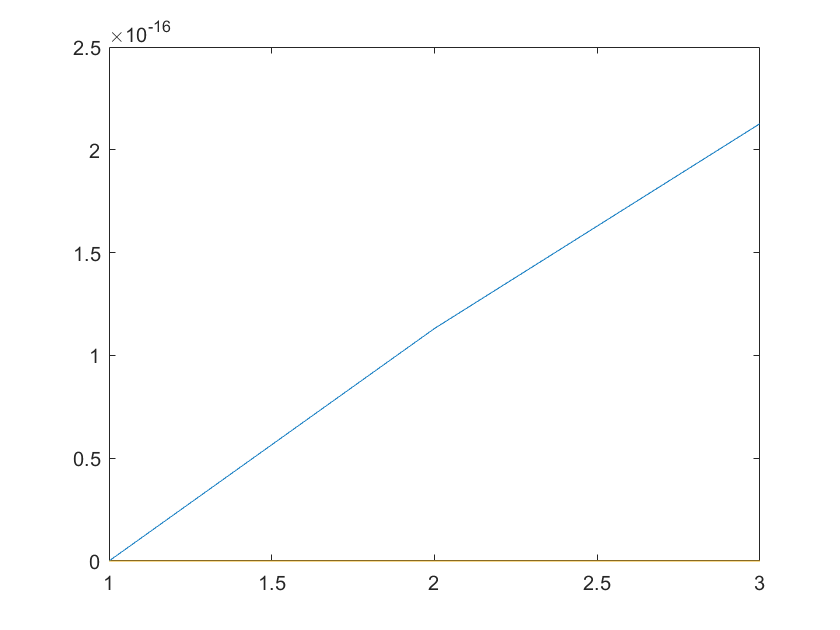


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

% Oefening 9
m = 200;
n = 50;
k = 1:50

k =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



B = randn(m,n);
[Q,~] = qr(B,0)

Q =    -0.0193   -0.0220   -0.0286    0.0304    0.0098    0.0354    0.1072   -0.0324    0.0227    0.0374    0.1470    0.0471   -0.0122    0.0971    0.0655    0.0218    0.0635   -0.0132   -0.0459   -0.1945    0.0118   -0.0737   -0.1193   -0.0907   -0.1192    0.0273    0.0326    0.0806   -0.0073    0.0010   -0.0124   -0.1509   -0.0551    0.0525   -0.0810   -0.0219    0.0312    0.0695    0.0341    0.0471    0.0100   -0.1146   -0.0444   -0.0373    0.0275    0.0037    0.0183   -0.0105   -0.0258    0.1186
    0.1143   -0.0258   -0.0563   -0.0829   -0.0850   -0.0159   -0.0136    0.0691    0.0542    0.0201    0.1061    0.0760   -0.1161    0.0783    0.0104   -0.0484    0.1184   -0.0349   -0.0618    0.0167    0.0375   -0.1095    0.0706   -0.0027    0.0441    0.0556   -0.0709   -0.0172    0.0306    0.0176   -0.0816   -0.0663    0.1008    0.0997   -0.1949    0.0530   -0.1223   -0.0486    0.0798    0.0519    0.0469    0.0361    0.0917    0.1010   -0.0209    0.0885   -0.0584   -0.0895    0.0181   -0


V = randn(n) % change this to orthogonal matrix

V =     0.6295   -0.4867   -1.5638    0.5303    1.0190   -0.9398   -1.3200   -0.2689    0.3301   -0.8210   -1.0075   -0.3976   -0.9984   -2.4863    1.0967    0.7658    1.7721    1.3355    1.9405    0.3991    1.3094   -1.7701    0.3787    0.6552   -1.1367    0.2963   -0.3827    1.9708    0.0461   -0.0737    0.8610    0.0358    0.5748   -0.1253    0.0955   -0.1355    1.6693    1.8147    0.0056   -0.2865   -1.5120    0.2359   -1.4901   -1.1898    1.1010    0.0578   -1.1391    0.4239    0.4583   -0.9254
    0.8490    0.8723   -0.8011   -0.7587   -0.0539    0.0493   -1.2457    0.8104   -1.2219   -0.2151    0.6121   -1.3201   -2.1035   -0.1719   -0.1446   -0.8195   -0.6670    0.0927   -0.4897   -0.2288    1.1387   -0.4209    0.3789    0.1840   -1.3299   -0.5835    0.8251    2.7038   -0.9141    0.3907   -0.0927   -1.4893    0.8515    0.7821    1.0521   -1.9896   -0.2778    0.4501    0.1285   -0.8998    0.9392    0.5463   -1.1916   -1.0884    0.3395    1.1354    1.2316   -1.3922   -0.2785   -1


D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D

D = D(:,:,1) =

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   


A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A

A = A(:,:,1) =

    1.3408   -0.7511    0.7203   -0.0285   -0.6573    0.5901    1.0579   -0.5054   -0.3811   -0.7623   -0.2673   -0.4376   -0.5299    0.3460    0.8666   -0.1880    1.0957   -1.1299   -1.2539   -0.6919    0.2434   -0.8596    1.5848    0.9045    0.4099    0.7381   -1.2868    0.6062   -0.5697    0.6752    0.3238    0.2967   -0.1515   -1.6396   -0.2664   -0.7844   -1.5914   -1.2120    0.6821   -0.6596    0.6049   -0.8579    0.4061    0.5115   -0.7797    0.3056   -1.0814    0.9233    0.0987    0.0838
   -0.3505   -0.5774    0.9341   -0.6863   -0.3494    0.7534   -0.4568    0.2486   -0.2328   -0.2616   -0.2713    0.6650   -1.2927   -0.8275    0.0443    0.3744    0.0469    0.8349    0.2559   -1.2705    0.5799    0.7535    0.4207    0.3101   -0.2316   -0.9395   -1.0194   -0.1469    0.7440   -2.0553    0.2989    0.3698   -0.3373   -0.5902   -0.1919   -0.6110   -0.0812    0.4130    0.6752   -1.1864   -0.9759   -0.1325    0.1267    0.3458    1.3329    0.4831   -0.1298   -0.2222   


K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 	1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



% Oefening 10
Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1

Q1 = Q1(:,:,1) =

    0.1129   -0.0956    0.0483    0.0221   -0.0566    0.0860    0.0871    0.0071   -0.0743   -0.0823   -0.0412   -0.0266   -0.0412    0.0557    0.1045    0.0011    0.0827   -0.0638   -0.0104   -0.0529   -0.0126    0.0508    0.0371    0.1181    0.0204    0.0045   -0.0907    0.0602    0.0029    0.0844   -0.0602    0.0967    0.0169   -0.0380    0.0672   -0.0703   -0.1342   -0.0538    0.0329    0.1376    0.0775    0.0021   -0.0290    0.0374    0.0530   -0.1469   -0.0180    0.0713    0.0196   -0.0244
   -0.0295   -0.0569    0.0780   -0.0486   -0.0616    0.0981   -0.1372    0.0225    0.0174   -0.0177   -0.0757    0.1172   -0.0842   -0.0931    0.0461    0.0220   -0.0003    0.0957   -0.0496   -0.0975   -0.0188    0.1116    0.0143    0.0078   -0.0470   -0.0541   -0.0731   -0.0106    0.0545   -0.0867    0.0333    0.0051   -0.0834   -0.1687   -0.0937   -0.0828    0.0188   -0.0040    0.0113    0.0835   -0.0942   -0.0852    0.0411    0.0195    0.0449   -0.0448   -0.0085   -0.0074 


Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2

Q2 = Q2(:,:,1) =

    0.1129   -0.0956    0.0483    0.0221   -0.0566    0.0860    0.0871    0.0071   -0.0743   -0.0823   -0.0412   -0.0266   -0.0412    0.0557    0.1045    0.0011    0.0827   -0.0638   -0.0104   -0.0529   -0.0126    0.0508    0.0371    0.1181    0.0204    0.0045   -0.0907    0.0602    0.0029    0.0844   -0.0602    0.0967    0.0169   -0.0380    0.0672   -0.0703   -0.1342   -0.0538    0.0329    0.1376    0.0775    0.0021   -0.0290    0.0374    0.0530   -0.1469   -0.0180    0.0713    0.0196   -0.0244
   -0.0295   -0.0569    0.0780   -0.0486   -0.0616    0.0981   -0.1372    0.0225    0.0174   -0.0177   -0.0757    0.1172   -0.0842   -0.0931    0.0461    0.0220   -0.0003    0.0957   -0.0496   -0.0975   -0.0188    0.1116    0.0143    0.0078   -0.0470   -0.0541   -0.0731   -0.0106    0.0545   -0.0867    0.0333    0.0051   -0.0834   -0.1687   -0.0937   -0.0828    0.0188   -0.0040    0.0113    0.0835   -0.0942   -0.0852    0.0411    0.0195    0.0449   -0.0448   -0.0085   -0.0074 


Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3

Q3 = Q3(:,:,1) =

    0.1129   -0.1106    0.0296    0.0490   -0.0223    0.1007   -0.0156    0.0600   -0.0092   -0.0616   -0.0835   -0.0699   -0.0537    0.0014   -0.0013   -0.0181   -0.0143   -0.0583   -0.0464   -0.0885   -0.0825    0.0690   -0.0708    0.0820   -0.0401   -0.0069    0.0061   -0.0407    0.0548    0.0371    0.0949   -0.0291    0.0539   -0.0288   -0.0169   -0.0694   -0.0632   -0.0017   -0.0494    0.0477    0.0532    0.0282   -0.0512    0.0398    0.0634   -0.0788   -0.0339    0.0073   -0.0360   -0.0393
   -0.0295   -0.0522    0.0743   -0.0425   -0.0791    0.0759   -0.1447    0.0352    0.0425   -0.0124   -0.1001    0.0632   -0.0455   -0.0941    0.0119   -0.0055   -0.0430    0.1505   -0.0641   -0.0516   -0.0518    0.1048   -0.0112    0.0197   -0.0905    0.0505    0.0703   -0.0532    0.0704    0.0692    0.0057   -0.0673    0.0630   -0.0696   -0.0994    0.0199   -0.0704   -0.0775   -0.0663    0.0727    0.0651    0.0684   -0.0465    0.0674    0.0378   -0.0642   -0.0784    0.0613 


orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i)'*Q1(:,:,i));
end
orth1

orth1 =     0.0000
    0.0000
    0.0000
    0.0001
    0.0003
    0.0012
    0.0050
    0.0153
    0.0492
    0.1222



orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i)'*Q2(:,:,i));
end
orth2

orth2 =     0.0029
    0.0029
    0.0049
    0.0079
    0.0117
    0.0200
    0.0354
    0.0746
    0.1040
    0.1870



orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i)'*Q3(:,:,i));
end
orth3

orth3 =    29.3385
   27.7330
   27.1359
   27.2516
   24.8840
   32.7575
   39.1966
   38.4238
   28.1325
   30.6227


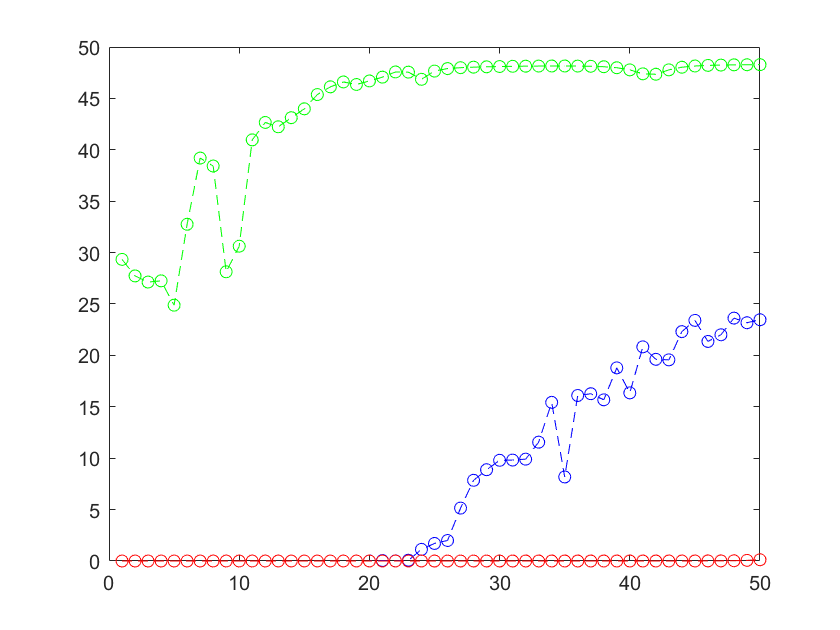


plot(k, orth1, 'b--o', k, orth2, 'r--o', k, orth3, 'g--o')


%Fout is veel te groot voor KLGS en herGS, kan niet!

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

[V,H] = Arnoldi(A,v,m)

V =     0.0525   -0.0271   -0.0149   -0.0496    0.0053   -0.0430    0.0900    0.0025   -0.0645   -0.0511    0.0149   -0.0367    0.0129    0.0122   -0.0386    0.0220    0.0236   -0.0679   -0.0142    0.0158   -0.0227    0.0163    0.0336   -0.0213    0.0452   -0.0278   -0.0508   -0.0138    0.0263    0.0188   -0.0185   -0.0385    0.0197    0.0081   -0.0352   -0.0363   -0.0159    0.0455    0.0013   -0.0134   -0.0108    0.0714    0.0014    0.0531   -0.0027   -0.0172    0.0520    0.0345   -0.0088    0.0056
    0.0439   -0.0114    0.0197    0.0065    0.0374    0.0066    0.0223   -0.0212    0.0112   -0.0159    0.0148   -0.0366    0.0241    0.0101   -0.0062   -0.0431    0.0465    0.0019   -0.0071   -0.0404   -0.0458    0.0016   -0.0226    0.0151    0.0378   -0.0474   -0.0596    0.0123   -0.0008   -0.0587   -0.0241    0.0113   -0.0104   -0.0399   -0.0070    0.0000   -0.0398    0.0161    0.0457    0.0258   -0.0654   -0.0438   -0.0057    0.0533   -0.0115   -0.0251   -0.0104    0.0080    0.0269   -0

H =   236.9719  137.1200    5.3250    0.4335   -0.1580   -0.0224   -1.1183   -0.0362   -0.2107    0.3321    0.6074    0.4990    0.3136   -0.0561   -0.2677    0.3580   -0.8565    0.3565   -0.6578    0.2846    0.3289    0.1042   -0.1981    0.4094   -0.4054    0.6402   -0.1116   -0.4426    0.2152   -0.5030    0.4745    0.0792    0.8458    0.0944    0.1994   -0.3226   -0.1582    0.1418   -0.3405   -0.8280   -0.2096    0.6813   -0.3450    0.2552   -0.0113   -0.2507    0.2135   -0.0976   -1.0268    0.6039
  137.3414   78.7402    2.8217    0.2112    0.1725    0.1532   -0.1737   -0.0273    0.2765   -0.0346    0.2210    0.9450    0.5320   -0.4701    0.1052    0.9447   -0.3876    0.3188   -0.5185    0.2393    0.6638   -0.1037    0.1240   -0.5514   -0.1066   -0.1325   -0.6548   -0.2446    0.7861   -0.1740   -0.3457    0.0257    0.0181   -0.6117    0.2242    0.0985   -0.2406   -0.1495   -0.2667   -0.2828   -0.4785    0.5574   -0.9390    0.0599    0.0374    0.2191    0.3911    0.2896    0.1652    0